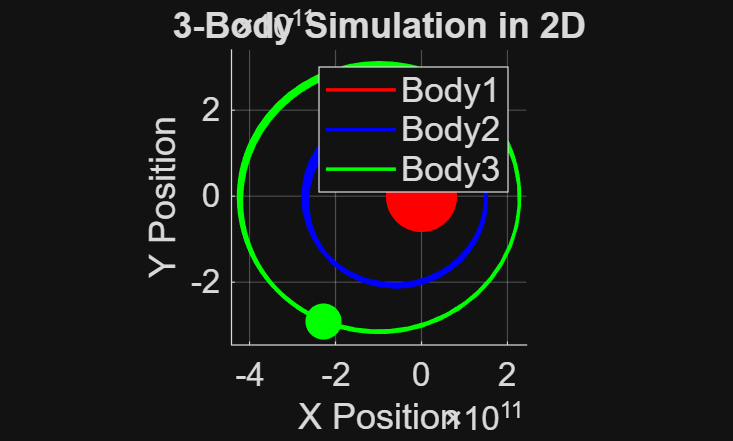

clear all; clc;close all;

% Parameterse
G =  6.674e-11;% Gravitational constant in arbitrary units
m1 = 1.989e30; % Mass of body sun
m2 = 5.972e24; % Mass of body earth
m3 = 6.39e23; % Mass of body mars
R12 = 1.496e11;
R13 = 2.279e11;

v12 = sqrt(G*m1/R12);
v13 = sqrt(G*m1/R13);

beta = 2.01;

% Initial
% positions and velocities [x1, y1, x2, y2, x3, y3, vx1, vy1, vx2, vy2, vx3, vy3]

% Initial conditions for figure-eight orbit
%
initial_conditions = [ ...
     0, 0, ... % x1, y1
     R12,0 ... % x2, y2
     R13,0 ... % x3, y3
     0, 0,   ... % vx1, vy1
     0, v12, ... % vx2, vy2
     0, v13  ... % vx3, vy3
];   

%}

% Time span
tspan = [0, 315360000];

% Solve the ODEs using ode45
f=@(t, Y) threeBodyODE(t, Y, G, m1, m2, m3,beta);

options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10);
[t, Y] = ode45(f, tspan, initial_conditions);

% Plot and animate

markerSizes=[30,15,15];
legendNames={'Body1','Body2','Body3'};

% threeBodyPlot(Y,initial_conditions, markerSizes, legendNames);

speed=1; % normalized framerate
threeBodyAnimation(Y,speed,markerSizes, legendNames,1);


%}